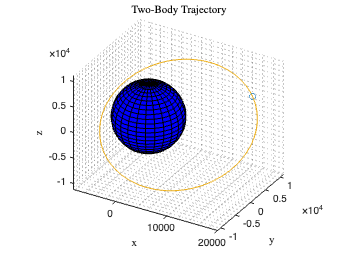

% CALCULATIONS

% Creating Inputs for Numerical Integration

%Inital Conditions
Y0 = [20000; 0; 0; 0; 2.9; 1.8]; % [x; y; z; vx; vy; vz] [km, km/s]

tspan = [0 24*60*60]; % One day in [s]

options = odeset('RelTol', 1e-13); % Setting a tolerance
% Tolerance is set very small for precision

% Numerical Integration
[t, Y] = ode113(@ODE2BP, tspan, Y0, options);

% Pulling Position Data [x,y,z] from Output of ODES
x = Y(:, 1); % [km]
y = Y(:, 2); % [km]
z = Y(:, 3); % [km]

% VISUAL FIXES

% Creating Figure
figure; hold on
%TITLES AND LABELS
title('Two-Body Trajectory', 'Interpreter', 'Latex')
xlabel('x', 'Interpreter', 'Latex')
ylabel('y', 'Interpreter', 'Latex')
zlabel('z', 'Interpreter', 'Latex')

%Ensures scaling of axis is equal
axis equal
%Adds 'Minor Grid Lines'
grid minor
%Sets 'Azimuth' & 'Elevation' angles changing the perspective of the plot but can easily be manipulated in finder.
view(30,30)

% PLOTTING

% Creating/Plotting Spherical Earth at Origin [0,0]
rm = 6378.14; % Radius of Earth [km]
[xEarth, yEarth, zEarth] = sphere(25);
surf(rm*xEarth,rm*yEarth,rm*zEarth, 'FaceColor', [0 0 1]);

% Plotting Trajectory
comet3(x, y, z, 0.1)
hold off

function dYdt = ODE2BP(t, Y)
% User-Defined Ordinary Differental Equation Solver Function
% Outputs variables t & y [numerical intergreation time steps] & [state
% vector at each time step]

    mu = 3.986*10^5; % Earth's gravitational parameter [km^3/s^2]

    x = Y(1); % [km]
    y = Y(2); % [km]
    z = Y(3); % [km]
    vx = Y(4); % [km/s]
    vy = Y(5); % [km/s]
    vz = Y(6); % [km/s]

    xddot = -mu/(x^2+y^2+z^2)^(3/2)*x; % [km/s^2]
    yddot = -mu/(x^2+y^2+z^2)^(3/2)*y; % [km/s^2]
    zddot = -mu/(x^2+y^2+z^2)^(3/2)*z; % [km/s^2]
    % time derivative state vector (User-Def Fnc's must be at end of Script)
    dYdt = [vx;vy;vz;xddot;yddot;zddot]; % Y'
    % Returns a new vector dYdt that will be used by ode113 to numerically
    % intergrate
end